**The cart and pole system**

Consider the cart-and-pole system here depicted:

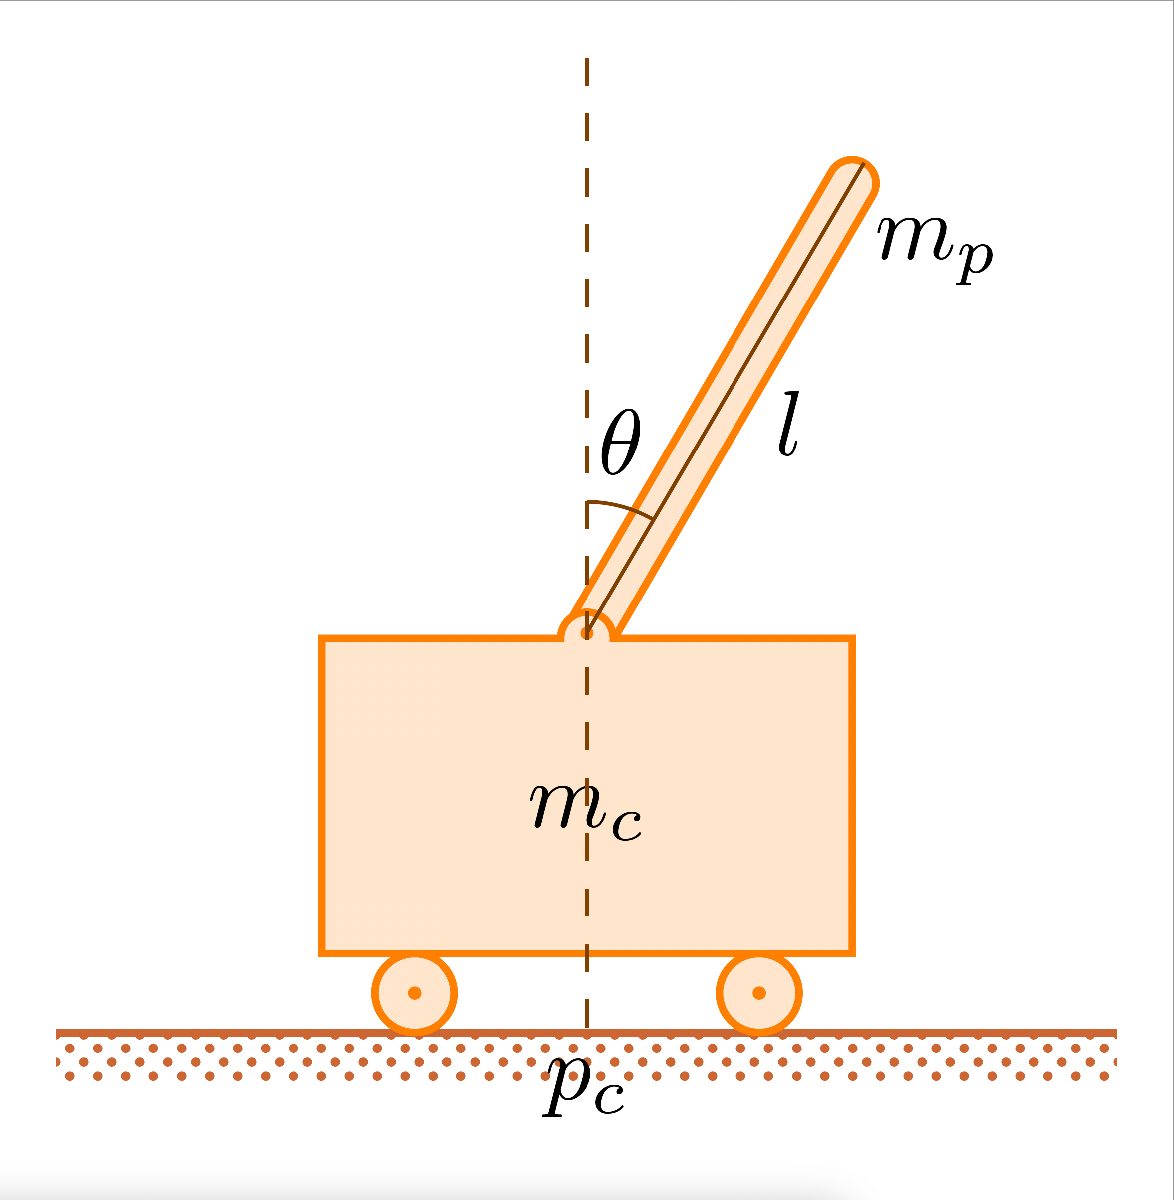

whose dynamics follows the following equations:


$$  \ddot{p}_c=\frac{F\,+\,m_p\,l\,\left[\dot{\theta}^2\,\sin\left(\theta\right)\,-\,\ddot{\theta}\,\cos(\theta)\right]}{m_c\,+\,m_p}$$



$$\ddot{\theta}=\frac{g \sin(\theta)\,+\,\cos(\theta) \left[ \frac{-F\,-\,m_p\,l\,\dot{\theta}^2 \sin \left(\theta\right)\,+\,\mu_c\,\text{sgn}\left(\dot{p}_c\right)}{m_c\,+\,m_p}\right]-\frac{\mu_p\dot{\theta}}{m_p\,l}}{l\,\left[\frac{4}{3}-\frac{m_p\,cos^2\left(\theta\right)}{m_c\,+\,m_p}\right]}$$
   


$$(*)$$


where $g = 9.8\,\text{m/sec}$ is the gravitational acceleration, $m_c = 1\,\text{kg}$ is the cart mass, $m_p = 0.1\,\text{kg}$ is the pole mass, $l = 0.5\,\text{m}$ is the half-pole length, $\mu_p = 0.000002$ is the pole on cart friction coefficient, and $F:|F|\leq 10\,\text{N}$ is the force applied to cart's center of mass.

1. Clearly define an optimal control problem for pole balancing.

Pole balancing represents a fundamental challenge in control theory, aiming to preserve the equilibrium of an inverted pendulum (pole) on a dynamic platform. The optimal control problem in pole balancing revolves around identifying a control policy that minimizes a cost function while upholding system stability.

**System Dynamics:**

Contemplate a straightforward inverted pendulum system featuring a horizontally mobile cart. The system's state is defined by the cart's position $(pc)$ and the pole's angle $(\theta)$. The system dynamics can be represented through differential equations, such as the non-linear equations of motion governing an inverted pendulum.

**Objective:**

Establish a cost function designed to encapsulate both the performance and stability of the system. The primary goal is to identify a control policy that minimizes this cost function within a defined time horizon.

The optimal control problem involves defining the control input $u(t)$ that minimizes the cost function$J(x(t), \theta(t), u(t))$, subject to the system dynamics and constraints:


$$\[ \min_{u(t)} J(x(t), \theta(t), u(t)) \]$$


This minimization is carried out while adhering to the dynamics of the system and any specified constraints. The solution to this optimal control problem results in a control policy that effectively stabilizes the inverted pendulum, meeting the prescribed performance criteria.

2. Is the LQR applicable in its simple form on the system? If not what is missed?

No, because the system needs to be linearized.

3. Design an LQR for the linearized version of the cart and pole obtained in the previous hands-on. Justify all the design choices and perform all the required checks

close all
clear
clc

load cart_pole_matrix_lin.mat;

cp_cont = ss(A, B, C, D);  %computing the continuous system
cp_dis = c2d(cp_cont, 0.01);  %computiung the discrete system from the previous one

obs_matrix = obsv(cp_dis.A, cp_dis.C);  %computing the observable matrix
is_obs = length(A) - rank(obs_matrix)  %check if the system is fully observable (ZERO means observable)

is_obs = 0

reach_matrix = ctrb(cp_dis.A, cp_dis.B);  %computing the reachable matrix
is_reach = length(A) - rank(reach_matrix) %check if the system is fully reachable (ZERO means reachable)

is_reach = 0

R = 10;    
Q = [1  0  0  0;
     0  0  0  0;
     0  0  10  0;
     0  0  0  0];

K= dlqr(cp_dis.A, cp_dis.B, Q, R)  %the command provide the vector K for an infinite horizon control

K =    -0.3028   -0.9543  -25.5205   -6.4607


4. Simulate the linearized cart and pole system controlled by an LQR. Plot the significant behaviors

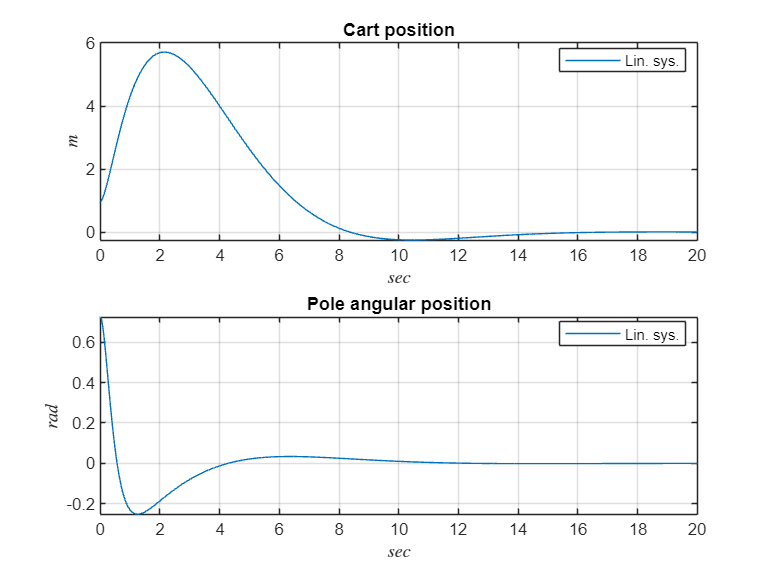

Acl = cp_dis.A - cp_dis.B * K;
Bcl = cp_dis.B;
Ccl = cp_dis.C;
Dcl = 0;

x_0 = rand(1,4);   %generate random initial condition
x_0_non_lin = x_0;

x_anim = x_0;

Ts = 0;
for i=1:1:2001
    Ts = [Ts Ts(end)+0.01]; %#ok<*AGROW>
end

cp_cl = ss(Acl, Bcl, Ccl, Dcl, 0.01);   %computing the discrete system with the lqr control

j1 = 1;
u = [0 -K*x_0'];

for i=1:1:2001

    [x, t] = lsim(cp_cl, [0 -K*x_0'], Ts(i):0.01:Ts(i+1), x_0);
    
    sz = size(x);
    
    j2 = j1 + sz(1)-1;

    xout(j1:j2, :) = x;
    tout(j1:j2, :) = t;

    x_anim = [x_anim; x(end, :)];

    j1 = j2;

    x_0 = x(end, :);
    u(1) = u(2);
    u(2) = -K*((x_0'));
    
end

subplot(2,1,1);
plot(tout, xout(:,1));
xlabel("$sec$", Interpreter="latex");
ylabel("$m$", Rotation=90, Interpreter="latex");
grid on
legend("Lin. sys.", Location="best");
xlim([0 20]);
title("Cart position");

subplot(2,1,2);
plot(tout, xout(:,3));
grid on
legend("Lin. sys.", Location="best");
title("Pole angular position");
xlabel("$sec$", Interpreter="latex");
ylabel("$rad$", Rotation=90, Interpreter="latex");
xlim([0 20]);

Animation of the system

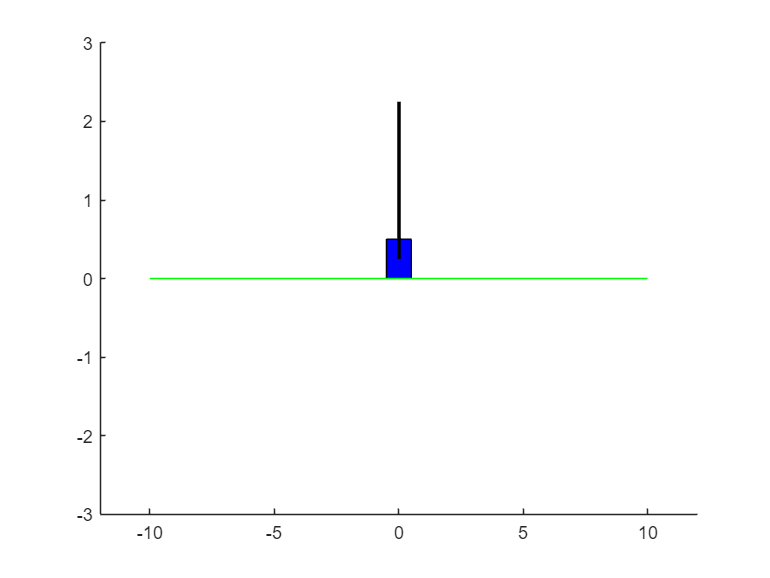

close all
animate_cartpole(Ts, x_anim);

5. Simulate the non-linear cart and pole system controlled by the previously obtained LQR. Plot the significant behaviors

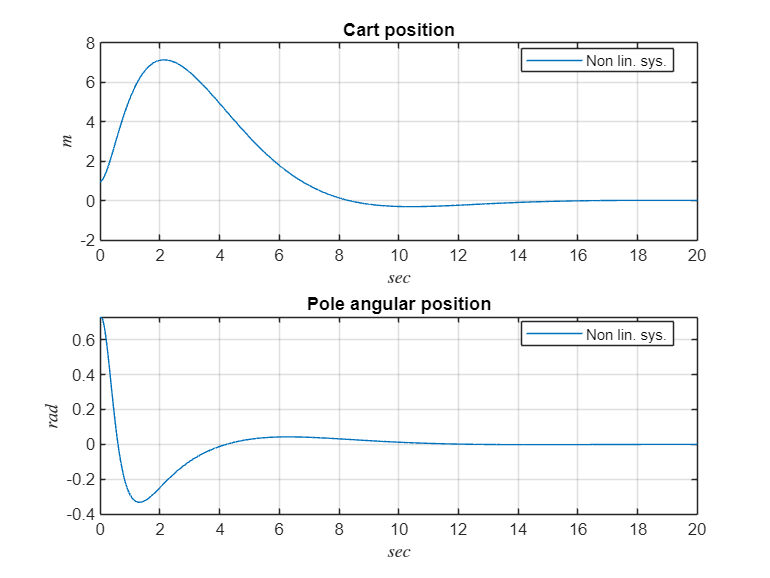

g = 9.8;
mc = 1;
mp = 0.1;
l = 0.5;
mu_p = 2e-6;

x_0 = x_0_non_lin;

x_anim = x_0;

Ts = 0;
for i=1:1:2001
    Ts = [Ts Ts(end)+0.01];
end

j1 = 1;
U = 0;

for i=1:1:2001

    [t, x] = ode45(@(t,x)cart_pend_for(t, x, g, mp, mc, l, mu_p, U), [Ts(i) Ts(i+1)], x_0);
   
    sz = size(x);
    
    j2 = j1 + sz(1)-1;

    xout_non_lin(j1:j2, :) = x;
    tout_non_lin(j1:j2, :) = t;

    x_anim = [x_anim; x(end, :)];

    j1 = j2;

    x_0 = x(end, :);
    U = -K*((x_0'));
end

subplot(2,1,1);
plot(tout_non_lin, xout_non_lin(:,1));
xlabel("$sec$", Interpreter="latex");
ylabel("$m$", Rotation=90, Interpreter="latex");
grid on
legend("Non lin. sys.", Location="best");
xlim([0 20]);
title("Cart position");

subplot(2,1,2);
plot(tout_non_lin, xout_non_lin(:,3));
grid on
legend("Non lin. sys.", Location="best");
title("Pole angular position");
xlabel("$sec$", Interpreter="latex");
ylabel("$rad$", Rotation=90, Interpreter="latex");
xlim([0 20]);

Animation of the system

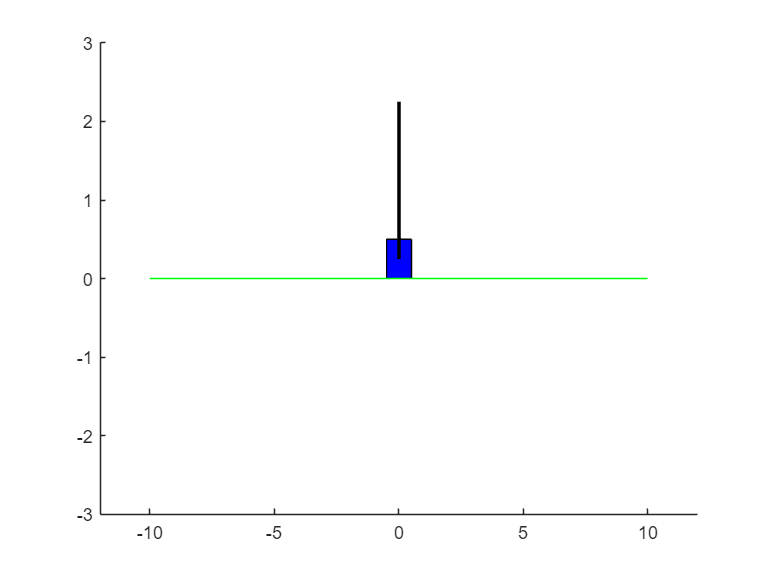

close all
animate_cartpole(Ts, x_anim);

6. Comment results obtained in the two simulations

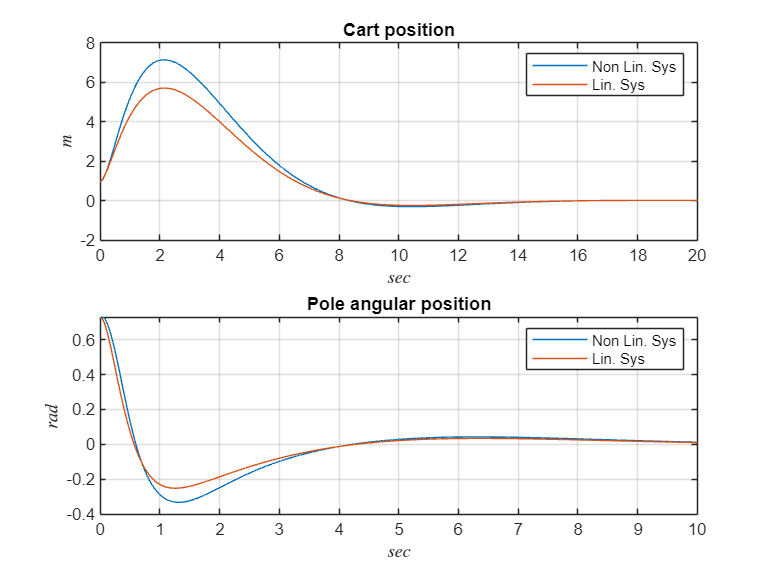

subplot(2,1,1);
plot(tout_non_lin, xout_non_lin(:,1));
hold on;
plot(tout, xout(:,1));
hold off;
xlabel("$sec$", Interpreter="latex");
ylabel("$m$", Rotation=90, Interpreter="latex");
grid on
xlim([0 20]);
title("Cart position");
legend("Non Lin. Sys", "Lin. Sys");

subplot(2,1,2);
plot(tout_non_lin, xout_non_lin(:,3));
hold on;
plot(tout, xout(:,3));
hold off;
grid on
title("Pole angular position");
xlabel("$sec$", Interpreter="latex");
ylabel("$rad$", Rotation=90, Interpreter="latex");
xlim([0 10]);
legend("Non Lin. Sys", "Lin. Sys");

The obtained outcomes differ because the discretized system matrices can provide an accurate approximation only when we are in proximity to the equilibrium point. It's evident that as the response moves away from equilibrium, the two curves diverge, while they overlap when approaching the equilibrium.

function dxdt = cart_pend_for(t, x, g, mp, mc, l, mu_p, U) %#ok<*INUSD>

  dxdt = zeros(4,1);

  dxdt(1) = x(2);
  dxdt(2) = (U+mp*l*((x(4)^2)*sin(x(3))-((g*sin(x(3))+ cos(x(3))*((-U-mp*l*(x(4)^2)*sin(x(3)))/(mc+mp))-((mu_p*x(4))/(mp*l)))/(l*((4/3)-((mp*cos(x(3))^2)/(mc+mp)))))*cos(x(3))))/(mc+mp);
  dxdt(3) = x(4);
  dxdt(4) = (g*sin(x(3))+ cos(x(3))*((-U-mp*l*(x(4)^2)*sin(x(3)))/(mc+mp))-((mu_p*x(4))/(mp*l)))/(l*((4/3)-((mp*cos(x(3))^2)/(mc+mp))));

end
function animate_cartpole(t, states)
    % Parameters for drawing
    cart_width = 1.0;
    cart_height = 0.5;
    pole_length = 2.0;

    figure;

    for i = 1:length(t)
        % Clear the figure
        clf;

        x = states(i, 1);  % Cart position
        theta = states(i, 3);  % Pole angle

        % Compute the pole's coordinates
        pole_x = x + pole_length * sin(theta);
        pole_y = cart_height / 2 + pole_length * cos(theta);

        % Cart
        rectangle('Position', [x - cart_width / 2, 0, cart_width, cart_height], 'FaceColor', [0, 0, 1]);

        % Pole
        line([x, pole_x], [cart_height / 2, pole_y], 'LineWidth', 2, 'Color', [0, 0, 0]);

        % Ground
        line([-10, 10], [0, 0], 'Color', [0, 1, 0]);


        xlim([-12, +12]);
        ylim([-pole_length - 1, pole_length + 1]);

        pause(0.01);
    end
end